# Quick Start Example: Accessing two-photon calcium imaging data from the Allen Brain Observatory

This example demonstrates access and basic analysis of the Visual Coding – 2P dataset [1] from the Allen Brain Observatory web resource [2]. This public dataset consists of 2 photon calcium imaging ('Ophys') experiments from a range of cortical areas and depths. 

The Brain Observatory Toolbox consists of functions and classes, contained within its top-level [package folder](https://www.mathworks.com/help/matlab/matlab_oop/scoping-classes-with-packages.html) +bot, which are referenced from MATLAB with the prefix `bot`.

#### Access the Visual Coding 2P dataset

The 2P data is grouped and organized into experimental `sessions`.  

To access sessions use the fetch function of the form `bot.fetchSessions('ophys'). `This retrieves tables of the available experimental *sessions *with session parameters.

Individual sessions can be queried from the table (using the row) or as an object (using the item id).

For example,` bot.session(session_id)` — Retrieves a single experimental session.

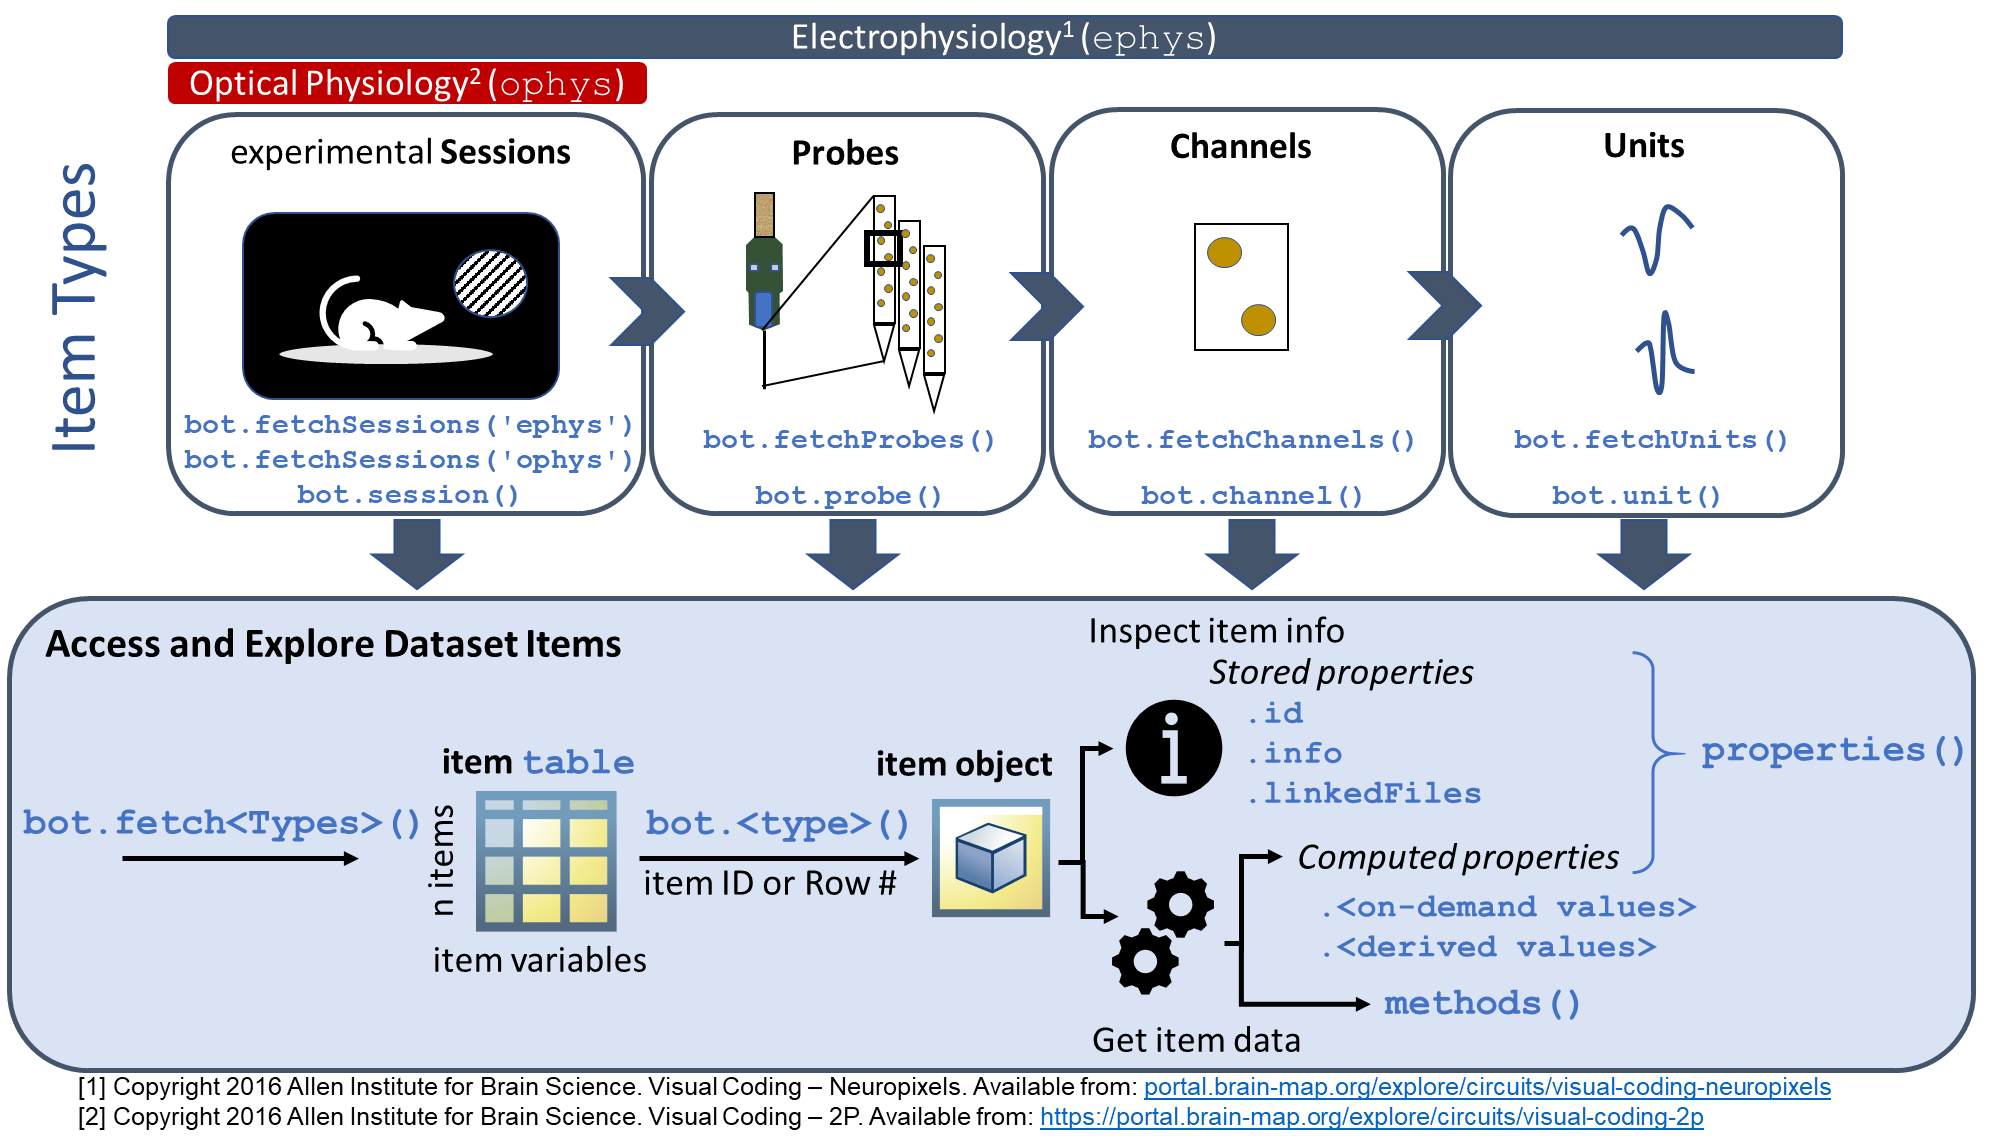

*Fig: Schematic showing relationship of the different *`LinkedDatasetItem`*s to each other and *`bot.fetch`* functions for accessing each.*The Brain Obervatory Toolbox represents the Visual Call of the available linked dataset contents can be retrieved from the Allen Brain Observatory web resource through a set of `bot.fetch<Types>` functions: Create a session filter object, using the `bot.sessionfilter` class. Since this is the first time we are using the Brain Observatory Toolbox, the manifest of all experimental data is downloaded from the Allen Brain Observatory resource [1].

availSessions = bot.fetchSessions('ophys');

Inspecting the size of thise table array with the command `whos` reveals the dataset is quite extensive:

whos availSessions 

  Name                  Size               Bytes  Class    Attributes

  availSessions      2684x14            68790384  table              



These dataset content table consists of rows of dataset items (`sessions`) whose column-oriented variables contain individual session information. Since tables are inherently two-dimensional, their size can also be expressed by their height (number of rows) and width (number of columns). Here the command `height` returns the number of sessions: 

disp("There are " + height(availSessions) + " available sessions in the Visual Coding - Neuropixels dataset")

There are 2684 available sessions in the Visual Coding - Neuropixels dataset


The Visual Coding 2P dataset consists of thousands of experimental sessions.

#### Inspect Available Sessions 

The `head` command can be used to inspect a table's structure via its first few rows. Let's inspect the available experimental sessions:

We can look at which cortical structures are available to analyse, then filter the available sessions to select only the data from primary visual cortex (`'VISp'`).

head(availSessions)

ans = 8×14 table
       id        experiment_container_id     stimulus_name     targeted_structure_acronym    fail_eye_tracking    imaging_depth        cre_line        date_of_acquisition                     name                     specimen_id    experiment_container      specimen      targeted_structure    well_known_files
    _________    _______________________    _______________    __________________________    _________________    _____________    ________________    ____________________    _____________________________________    ___________    ____________________

#### Select Sessions of Interest

Table [indexing operations](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html) can be used to select specific experimental sessions (rows) with attributes of interest (column values). For instance, by combining [dot notation with logical indexing](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html#mw_77d04ebd-b6f7-4ee9-93ac-1cc1fd7bc735), we can extract ("filter") sessions where the primary visual cortex ('`VISp`') was imaged in specific Cre lines (Cux2-CreERT2) at a cortical depth of 175 µm with accompanying eye tracking data during specific stimulus presentations.

% Select experiments from the most orientation/direction-selective areas of visual cortex 
filteredSessions = availSessions(ismember(availSessions.targeted_structure_acronym, categorical("VISp")), :);

% Select experiments with GCaMP6f expression enriched in Layer 2/3 and Layer 4 of cortex
filteredSessions = filteredSessions(filteredSessions.cre_line == "Cux2-CreERT2", :);

% Select experiments imaging from the shallowest depth in Layer 2/3
filteredSessions = filteredSessions(filteredSessions.imaging_depth == 175,:);

% Select experiments with eye tracking data available
filteredSessions = filteredSessions(~filteredSessions.fail_eye_tracking, :);

% Select experiments with drifting grating and natural movie stimuli
filteredSessions = filteredSessions(filteredSessions.stimulus_name == "three_session_A", :);

Only a few sessions remain

disp("Only " + height(filteredSessions) + " experimental sessions are now available")

Only 4 experimental sessions are now available


#### Create Session Object 

The Brain Observatory Toolbox defines [classes](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html) to represent individual Visual Coding 2P dataset items as [objects](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html). These objects can inspected and worked with via their defined [properties and methods](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html).

The `bot.session` function can be called to create an object representing the first session item in the `filteredSessions` table above:

These factory functions also can be supplied with a table array, whose rows will be converted to object array elements. For instance, easily create an object for the first session in `filteredSessions` via table indexing:

sessionUnderStudy = bot.session(filteredSessions(1,:)); 

This is a lightweight object; no experimental data has been downloaded, but we can examine some of the parameters of the session by accessing the object properties:

sessionUnderStudy.info    

ans = struct with fields:
                            id: 501836392
       experiment_container_id: 511510650
                 stimulus_name: three_session_A
    targeted_structure_acronym: VISp
             fail_eye_tracking: 0
                 imaging_depth: 175
                      cre_line: "Cux2-CreERT2"
           date_of_acquisition: 09-Feb-2016 18:02:52
                          name: "20160209_222425_3StimA"
                   specimen_id: 495727000
          experiment_container: [1×1 struct]
                      specimen: [1×1 struct]
            targeted_structure: [1×1 struct]
              well_known_files: [3×1 struct]


Now let's extract the fluorescence traces from the cells imaged in this session. This causes the session data to be downloaded from the Allen Brain Observatory, which takes longer to complete:

mfTraces = sessionUnderStudy.fluorescence_traces_dff;
vtTimestamps = sessionUnderStudy.fluorescence_timestamps;
whos mfTraces

  Name               Size                Bytes  Class     Attributes

  mfTraces      115772x178            82429664  single              



Now that we have the data for this session, let's plot a selection of the traces:

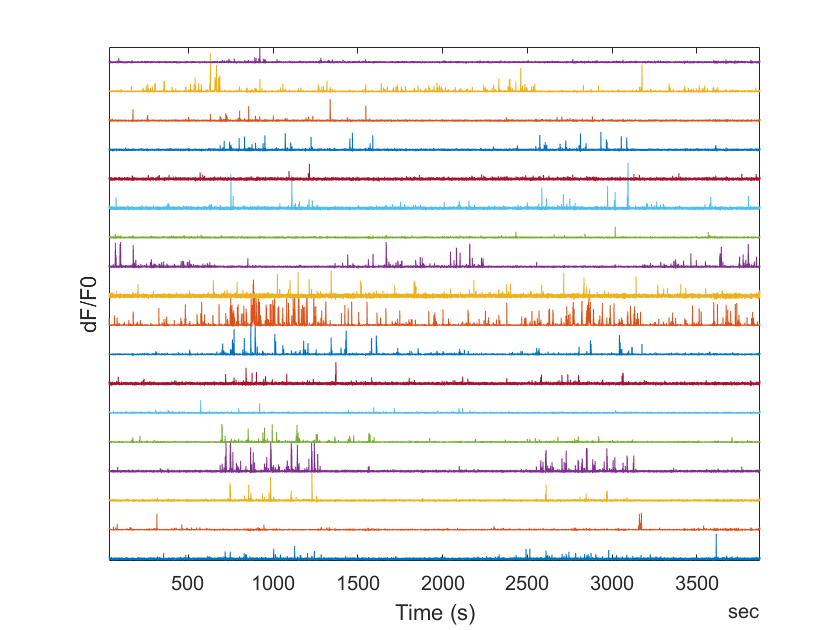

plot(vtTimestamps, bsxfun(@plus, mfTraces(:, 1:10:end), (0:10:size(mfTraces, 2))/3))

axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0')

It's also important to know what stimuli were presented, and at what time:

sessionUnderStudy.stimulus_list'

ans = 4×1 cell array
    {'drifting_gratings'  }
    {'natural_movie_one'  }
    {'natural_movie_three'}
    {'spontaneous'        }


The methods `getStimulusTable()` and `getStimulusTemplate()` can then be used to obtain detailed frame-by-frame information about the stimuli that were presented. 

getStimulusTable(sessionUnderStudy,'drifting_gratings') % details for stimulus drifting gratings

ans = 628×5 table
    temporal_frequency    orientation    blank_sweep    start_frame    end_frame
    __________________    ___________    ___________    ___________    _________

            15                 45             0             737           798   
           NaN                NaN             1             828           888   
             8                135             0             919           979   
             8                225             0            1009          1069   
             2                 45             0            1100          1160   
             2                270             0            1190          1250   
             8                 45             0            1281          1341   
             1                 90             0            1372          1431   
 

## References

[1] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [http://portal.brain-map.org/explore/circuits/visual-coding-2p](http://portal.brain-map.org/explore/circuits/visual-coding-2p)

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 